addpath 'Data'\ 'Utility Functions'\; 
load('Data\lvl2CSinfo.mat'); load('nonslipPlottingParamsMobility.mat');
load('Data\nonslipQuadMobility.mat');

hamr6_F = false;
switch hamr6_F
    case true
        dataMobility = 'Data\HAMR6_SE2_kinematicMobility.mat';
    case false
        dataMobility = 'Data\case_1_kinematicMobility.mat';
end
load(dataMobility);
set(groot,'defaultAxesTickLabelInterpreter','latex'); 
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Define the number of configurations we need.

discNum = 3;

First, we need the limb angle or 'nalpha' values at a certain point along the level-set of F - -1.2, 0, 1.2 in each direction. 

tX = linspace(-1.2, 1.2, discNum); tY = tX; % X: S13 % Y: S24
[tXmesh, tYmesh] = meshgrid(tX, tY); 
tYmesh = flipud(tYmesh); % flip the vertical coords to aid when plotting
stanceObjsInCells = {FRHLstance, FLHRstance};
nalpha = cell(1, 4);
for i = 1:numel(stanceObjsInCells)
    % if it is the first stance, use tX to get the joint angles, and then
    % if it is the second stance, use the other coordinate
    switch i
        case 1
            tNow = tXmesh;
        case 2
            tNow = tYmesh;
    end
    % get the current limb angles at the flow times denoted using interp1
    % and 'pchip' method
    % ... get the reference
    tVecNow = stanceObjsInCells{i}.aParaRef.t;
    yVecNow = stanceObjsInCells{i}.aParaRef.y;
    % ... get the angles interpolated
    yNowInCoords = interp1(tVecNow, yVecNow, tNow(:), "pchip");
    % ... iterate and distribute the values interpolated
    for j = 1:numel(stanceObjsInCells{i}.cs)
        nalpha{ stanceObjsInCells{i}.cs(j) } = reshape( yNowInCoords(:, j), size(tNow) );
    end
end

% some setup
% ... choosing submanifold index, nominal values for system parameters,
% ... position of the system offset from the origin
% ... convert body length to a numeric value
% ... choose randoming 
sIdx = cs_IdxFor2bGaits(strcmp(csString, 'Trot'), :);
na_bX = bodyScalingParam(end); na_bY = bodyScalingParam(end);
na = limbScalingParam(end);
nl = 1; bodyLength = double(subs(bodyLength, l, nl));
ngamma = gammaParam(end);
F_prctRm = 15;
nalpha0 = limbAngleParam(end);
% nx = bodyLength; ny = bodyLength; ntheta = pi/4;
nx = 0; ny = 0; ntheta = 0;

% colors
% ... body color will be a version of gray (also swing phase color)
% ... limb colors will be their corresponding stance phase colors
bodyColor = col(end, :); limbSwingColor = bodyColor; originColor = bodyColor;
limbStanceColor = cell(1, numLimbs); % computed in the loop
paramColor = bodyColor; % this will change when the parameter is varying
                        % ... plot color for the robot configuration
                        % ... and the figure box

% body frame information
gbody = fh_e__b(nx, ny, ntheta);
bodyX = gbody'*x_sel; bodyY = gbody'*y_sel; bodyTh = gbody'*theta_sel;

% plot body frames
bodyFrameX = bodyX*ones(1, 2); bodyFrameY = bodyY*ones(1, 2);
bodyFrameU = x_sel'*rot_SE2(bodyTh)*Cxy'; bodyFrameV = y_sel'*rot_SE2(bodyTh)*Cxy';

% init, iterate, and compute
pltBodyX = []; pltBodyY = []; pltBodyU = []; pltBodyV = []; % actual vars
pltLimbX = []; pltLimbY = []; pltLimbU = []; pltLimbV = [];
pltLimbX0 = []; pltLimbY0 = []; pltLimbU0 = []; pltLimbV0 = []; 
footX = []; footY = [];
pltLimbUnow = []; pltLimbVnow = []; % temp vars
footXnow = []; footYnow = [];
footXall = []; footYall = []; % accumulating vars for computing limits
for i = 1:numLimbs
    % body to offset base
    pltBodyX = [pltBodyX, bodyX]; pltBodyY = [pltBodyY, bodyY]; 
    pltBodyU = [pltBodyU, fz_b__bOff{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel];
    pltBodyV = [pltBodyV, fz_b__bOff{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel];
    % offset base to the body corners
    pltBodyX = [pltBodyX, (fh_e__boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel)'];
    pltBodyY = [pltBodyY, (fh_e__boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel)'];
    pltBodyU = [pltBodyU, (fz_boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel)'];
    pltBodyV = [pltBodyV, (fz_boxCorners{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel)'];
    % limb (actual position) and foot location
    pltLimbX = [pltLimbX, fh_e__ib{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*x_sel];
    pltLimbY = [pltLimbY, fh_e__ib{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta)'*y_sel];
    for k = 1:size(tXmesh, 1)
        for j = 1:size(tXmesh, 2)
            % ... load the temp vars
            pltLimbUnow = [pltLimbUnow, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha{i}(j, k))'*x_sel];
            pltLimbVnow = [pltLimbVnow, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha{i}(j, k))'*y_sel];
            footXnow = [footXnow, fh_e__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha{i}(j, k))'*x_sel]; 
            footYnow = [footYnow, fh_e__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, nalpha{i}(j, k))'*y_sel];
            footXall = [footXall, footXnow];
            footYall = [footYall, footYnow];
        end
    end
    % ... store data in actual vars
    pltLimbU{i} = pltLimbUnow;
    pltLimbV{i} = pltLimbVnow;
    footX{i} = footXnow; 
    footY{i} = footYnow;
    % ... wipe the temp vars
    pltLimbUnow = []; pltLimbVnow = [];
    footXnow = []; footYnow = [];
    % limb (origin)
    pltLimbX0 = [pltLimbX0, pltLimbX(i)]; pltLimbY0 = [pltLimbY0, pltLimbY(i)];
    pltLimbU0 = [pltLimbU0, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, 0)'*x_sel];
    pltLimbV0 = [pltLimbV0, fz_ib__i{i}(na_bX, na_bY, na, nl, ngamma, nx, ny, ntheta, 0)'*y_sel];
    % limb color based on stance
    limbStanceColor{i} = col(sIdx(logical(sum(cs(sIdx, :) == i, 2))), :);
end

% robot configuration plotting parameters
% ... some of these terms are defined based on the body length, so its
% ... defined locally as 4xl-- we need to convert this from symbolic to
% ... numerical form using the nominal value
% ... the limits are obtained from compute body and foot locations
% ... color for the limbs during swing phase
xPts = [0, pltBodyX, pltLimbX, footXall]; yPts = [0, pltBodyY, pltLimbY, footYall];
limX = [min(xPts), max(xPts)]; limY = [min(yPts), max(yPts)]; % compute the limits
bodyPlotThresh = 0.25*bodyLength*[-1 1]; % add a threshold
limX = limX+bodyPlotThresh; limY = limY+bodyPlotThresh; % augment the limits with threshold
scal = 30*bodyLength/4; % find a scaling-- you might have to play with this % multiplier values: 23.5 (thinner lines), 30 (better)
scaleDraw = max([diff(limX),diff(limY)])/scal;
lW = 1.2/scaleDraw; lW_r = 0.5/scaleDraw; lW_b = 0.8/scaleDraw;
lW_kq = 0.6/scaleDraw; lW_qf = 0.8/scaleDraw;
frame_scale = 0.10*bodyLength;
circS = 75/scaleDraw;

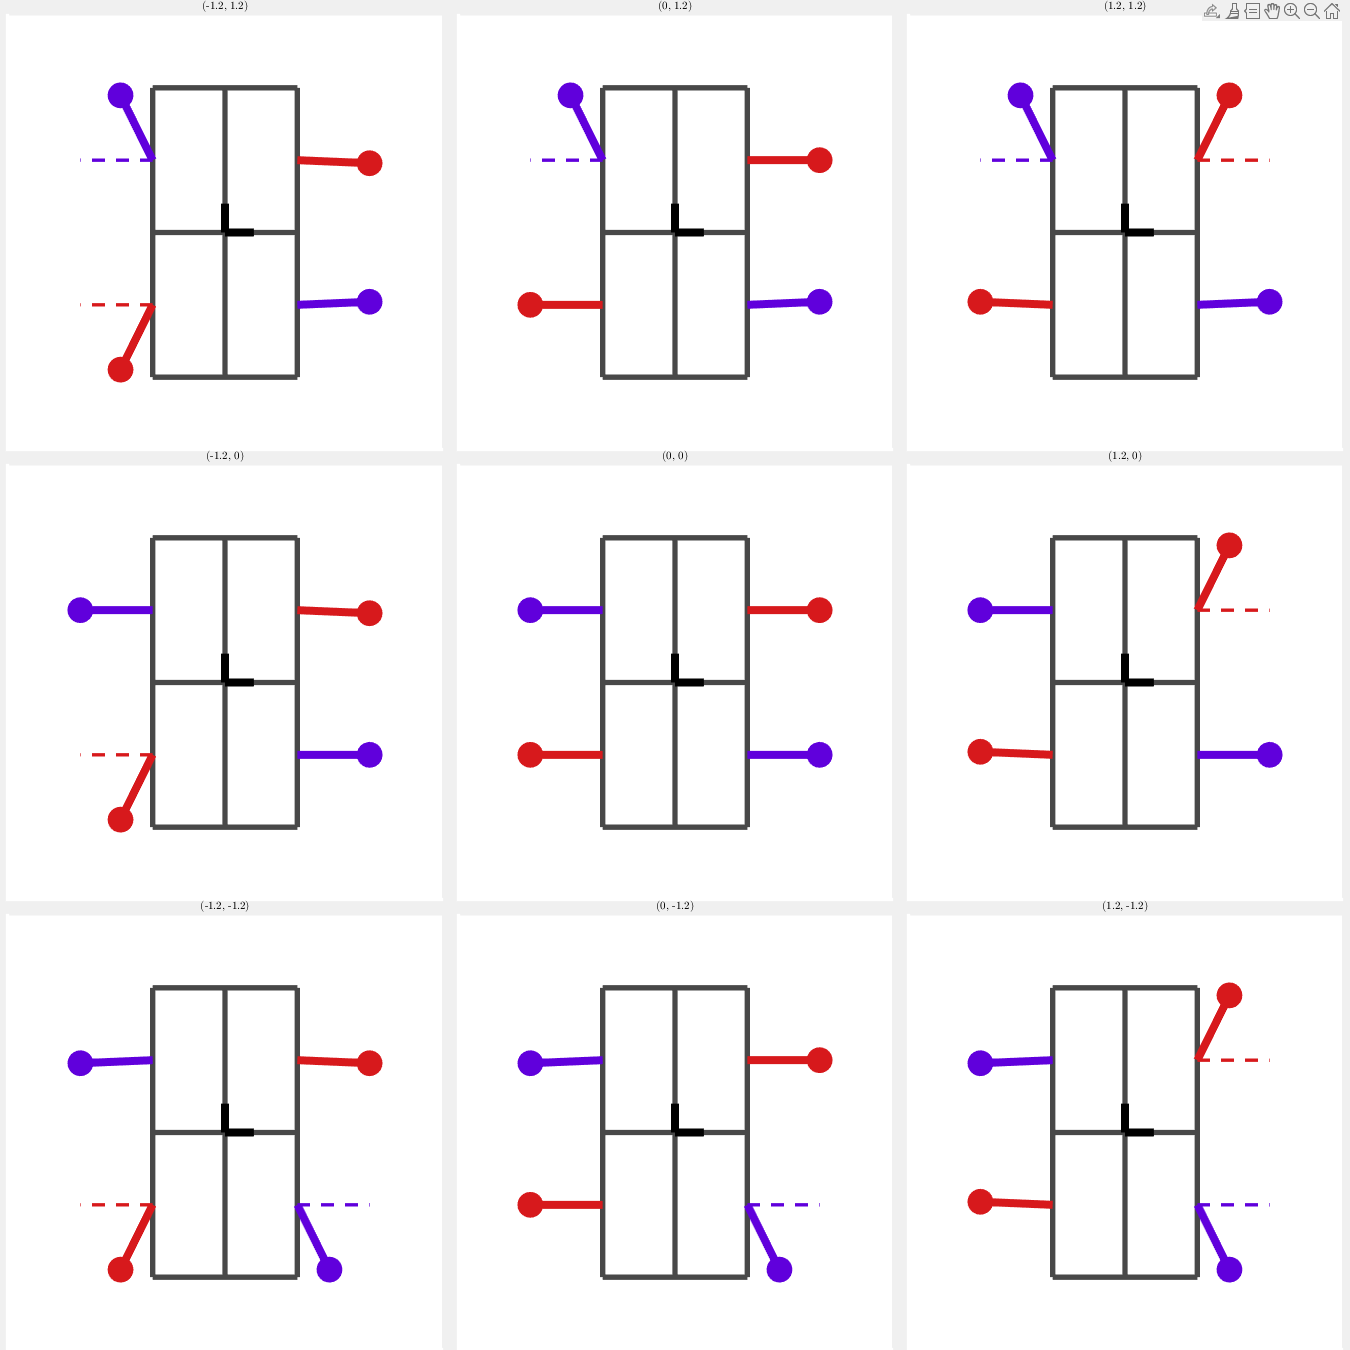

% plot the system
tileSizeInPix = 450; % 300, 450, 600
f = figure('units', 'pixels', ...
    'position', [0 0 numel(tX)*tileSizeInPix numel(tY)*tileSizeInPix], ...
    'Visible','on'); 
tl = tiledlayout(f, numel(tX), numel(tY), ...
    "TileSpacing", "tight", "Padding", "tight", ...
    "TileIndexing", "columnmajor"); % this will match the indexing with how 2D arrays are indexed with a single index

% plot each tile %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for tileIdx = 1:numel(tXmesh)
    % create the tile axes
    ax = nexttile(tl); hold(ax, "on");  box(ax, "off");
    % plot the body
    % ... first the body links
    % ... then the body frame
    quiver(ax, pltBodyX, pltBodyY, pltBodyU, pltBodyV,...
        "LineStyle", '-', "LineWidth", lW_b, "Color", paramColor, ...
        "AutoScale", "off", "ShowArrowHead", "off");
    hold on; axis(ax, "equal"); 
    quiver(ax, bodyFrameX, bodyFrameY, ...
        frame_scale*bodyFrameU, frame_scale*bodyFrameV,...
        "LineStyle", '-', "LineWidth", lW, "Color", 'k', ... % previous setup
        "AutoScale", "off", "ShowArrowHead", "off");
    % plot the limbs with respective stance phase colors
    for m = 1:numLimbs
        quiver(ax, pltLimbX(m), pltLimbY(m), pltLimbU{m}(tileIdx), pltLimbV{m}(tileIdx), ...
            "LineStyle", "-", "LineWidth", lW, "Color", limbStanceColor{m}, ...
            "AutoScale", "off", "ShowArrowHead", "off");
        scatter(ax, footX{m}(tileIdx), footY{m}(tileIdx), circS, limbStanceColor{m}, "filled");
        quiver(ax, pltLimbX0(m), pltLimbY0(m), pltLimbU0(m), pltLimbV0(m), ...
            "LineStyle", "--", "LineWidth", lW_r, "Color", limbStanceColor{m}, ...
            "AutoScale", "off", "ShowArrowHead", "off");
    end
    set(ax, 'xTick',[]); set(ax, 'yTick',[]); axis(ax, "equal");
    axis(ax, [limX, limY]); ax.LineWidth = 2*boxW;
    ax.XColor = ones(1, 3); ax.YColor = ones(1, 3);
    title(ax, ['(', num2str(tXmesh(tileIdx)),...
              ', ', num2str(tYmesh(tileIdx)), ')'], 'FontSize', 8);
end